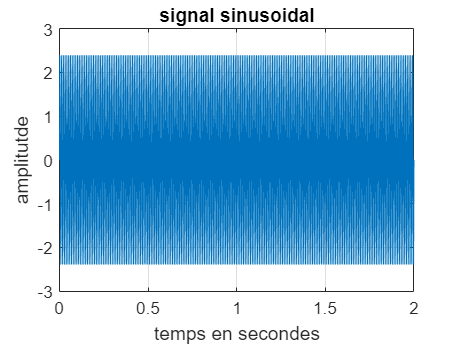

clear all;
close all;

% Génération d'une sinusoïde - Question a

% A (amplitude de la sinusoide) tq RSB = 5dB, RSB = 10log(Ps/Pb)
% puissance unitaire => Pb = 1
% puissance sinusoide = A²/2 = Ps
% A = sqrt(2sqrt(10))

f0 = 100;
fe = 500;
Te = 1/fe;
t = 0:Te:2;
A = sqrt(2*sqrt(10));

s = A*sin(2*pi*f0*t);

% Représentation signal s

figure;
plot(t ,s);
grid;
title("signal sinusoidal");
xlabel("temps en secondes");
ylabel("amplitutde");

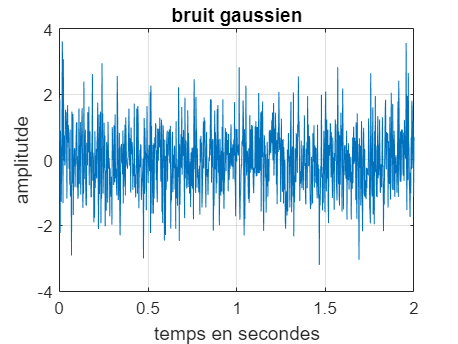


% Bruit b

b = randn(size(s));
b = b-mean(b); % moyenne nulle, mean = moyenne
b = b/std(b); % var = 1, std = variance

figure;
plot(t , b);
grid;
title("bruit gaussien");
xlabel("temps en secondes");
ylabel("amplitutde");

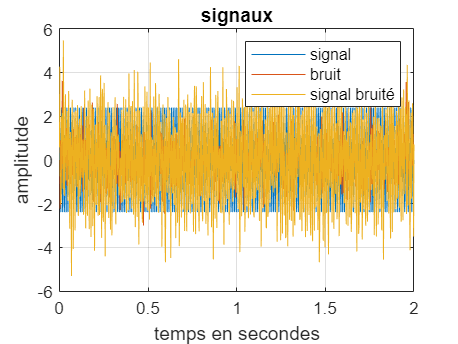


% Signal bruité sb

sb = s+b; 
figure;
plot(t, s, t, b, t, sb);
grid;
title('signaux');
legend('signal', 'bruit', 'signal bruité');
xlabel("temps en secondes");
ylabel("amplitutde");

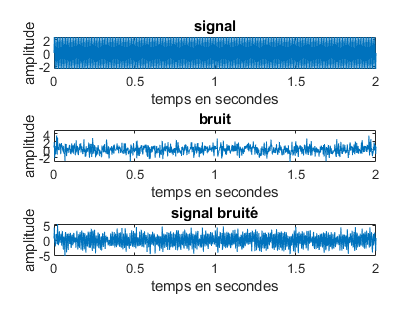


% Autre représentation 

figure;
subplot(311); % nombre de lignes, nombres de colonnes, classe
plot(t, s);
xlabel('temps en secondes');
ylabel('amplitude');
title('signal');
subplot(312);
plot(t, b);
xlabel('temps en secondes');
ylabel('amplitude');
title('bruit');
subplot(313);
plot(t, sb);
xlabel('temps en secondes');
ylabel('amplitude');
title('signal bruité');


% Calcul de l'énergie - Question b

% Avec une boucle for
tic;
su = 0;
for k=1 : length(s)
    su=su+s(k)^2;
end
toc;

Elapsed time is 0.013570 seconds.


E1=su

E1 = 3.1623e+03


% Avec une sum
tic;
E2=sum(s.^2)

E2 = 3.1623e+03

toc;

Elapsed time is 0.010844 seconds.



% Avec un produit vectoriel
tic;
E3=s*s'

E3 = 3.1623e+03

toc;

Elapsed time is 0.069442 seconds.



% Puissance théorique x nombre d'échantillons
Pth = A^2/2

Pth = 3.1623

Eth = Pth*length(s)

Eth = 3.1654e+03


% Moyenne du signal bruité
M1 = mean(sb)

M1 = 1.3797e-15

M2 = sum(sb)/length(sb)

M2 = 1.3797e-15

m = 0;
for k=1 : length(sb)
    m = m + sb(k);
end
M3 = m/length(sb)

M3 = 1.3675e-15